# Simple Video Stabilization with Template Matching 

In this example, you'll apply video stabilization to compensate for camera motion. While defining an ROI and updating your template image and ROI throughout the video are good practices, in some situations, they are not necessary. They are removed from this example so you can focus on the main steps of video stabilization without the added complication of updating your template and ROI. Work through the script section by section and examine the code. Ask us questions on the discussion forums if you have questions about what a section of code is doing.

**Note**: Running this script will write new video files to your current folder location.

## Initialization 

### Create Video Reader and Writer Objects

Run this section to create a `VideoReader` object for the shaky video and a `VideoWriter` object for the stabilized video.

shakyV = VideoReader("ShakyStreet.avi");
stableV = VideoWriter("simpleStabilizedVideo.avi");

### Create the Template Image

A good template should be distinct and, ideally, unique in the video. It also helps if the template has sharp edges with large changes in pixel values. Misaligning a sharp edge will result in a large sum of squared differences (SSD) value, reducing the chances of an incorrect match.

Read in the first frame of the video. Inspect the image in the Image Viewer app or in a figure window.  

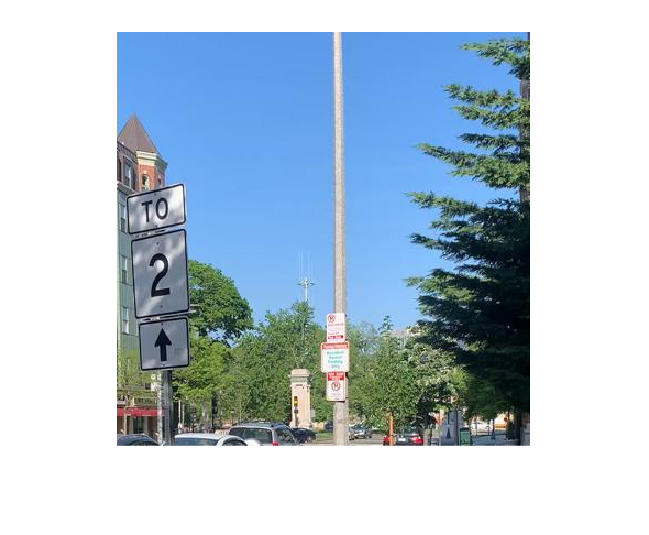

frame1 = read(shakyV,1);
imshow(frame1)

From inspection, the upper-right corner of the sign that says "To" is located at `[x, y] = [60 140]`. You need to crop a small region of the image centered at this location to use as a template. The `imcrop` function will crop a region using a 4-element vector `[xmin, ymin, width, height]`. 

Run this section to create the template image

templateOrigin = [60 140];
wt = 20;
ht = 20; 
xmin = templateOrigin(1) - round(wt/2);
ymin = templateOrigin(2) - round(ht/2);
template = imcrop(frame1,[xmin, ymin, wt, ht]);

Template matching is performed using grayscale images, so convert the template to grayscale.

template = im2gray(template);

View the template and the original image with a box of the template location.

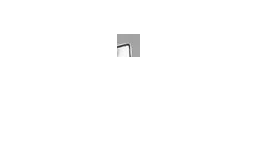

imshow(template)

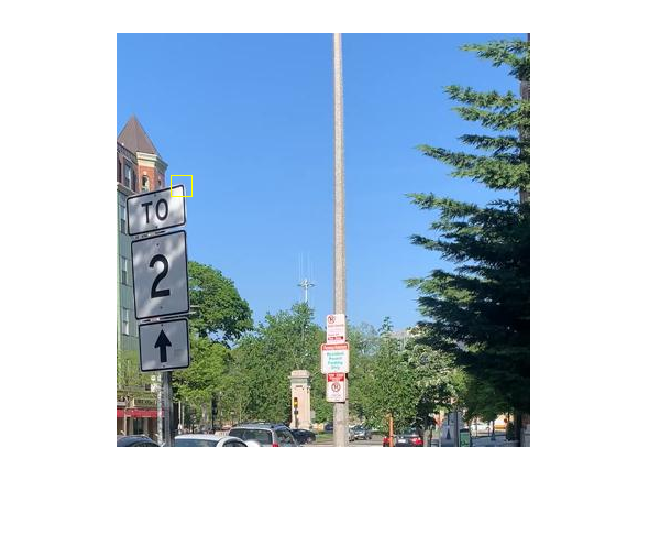

frame1 = insertShape(frame1,"Rectangle",[xmin, ymin, wt, ht]);
imshow(frame1)

This should be a good template. There are distinct edges, a corner, and bright pixels inside the sign and darker gray pixels outside the sign. 

## Stabilize the Video

Run this section to create a stabilized video. **This may take a minute or two to run and will write a file to your computer.** 

Loop through the frames in the video and:

- find the template position

- calculate the offset compared to the reference frame (this is the same as the cumulative motion)

- translate the frame to correct for motion

- write the corrected frame to the `VideoWriter` object

#### Max and Min Offsets

While not necessary, you may want to crop the video to include only the pixels that appear in every frame as you saw in the lesson. To do this, you need to keep track of the maximum and minimum offset translations in the x and y-directions for cropping after stabilization.

xMinOffset = 0;
xMaxOffset = 0;
yMinOffset = 0;
yMaxOffset = 0;

### Correct the Video

Create the `TemplateMatcher` object. In this example, no ROI is used.

templateMatcher = vision.TemplateMatcher();

Open the `VideoWriter` object for writing

open(stableV)

Get the number of frames and loop through the video.

nFrames = shakyV.NumFrames;
for ii = 1:nFrames
    currFrameColor = read(shakyV,ii);

    % Convert to grayscale for template matching
    currFrameGray = im2gray(currFrameColor);

    % Find the position of the template in the frame
    % Template matching is optimized for data type double, so convert the
    % inputs.
    currFrameGray = im2double(currFrameGray);
    template = im2double(template);
    templatePos = templateMatcher(currFrameGray,template);

    % templatePos is of data type int32
    % Convert to double to subtract the templateOrigin and calculate the
    % offset
    offset = double(templatePos) - templateOrigin;

    % Translate the color frame by the negative of the offset
    stabilizedFrame = imtranslate(currFrameColor,-offset);

    % Write the video
    writeVideo(stableV,stabilizedFrame);
    

The rest of the loop is for keeping track of the maximum offsets of the template as it moves throughout the video. This may or may not be necessary depending on your application. These values are used in the next code section to crop the video.

    % Check if the x and y offsets are larger or smaller than the current offset values. 
    % If so, update the current values to the new min/max.
    if offset(1) < xMinOffset
        xMinOffset = offset(1);
    end

    if offset(1) > xMaxOffset
        xMaxOffset = offset(1);
    end

    if offset(2) < yMinOffset
        yMinOffset = offset(2);
    end

    if offset(2) > yMaxOffset
        yMaxOffset = offset(2);
    end

    
end

Close the VideoWriter object

close(stableV)

## Post Processing

Use the offsets to crop the edges of the video so that only the pixel ranges that appear in all frames are included in the final video. To do this, you need the number of rows and columns of the image. 

nrows = size(frame1,1);
ncols = size(frame1,2);

The x and y minimum offsets are either negative or 0. Therefore, the starting column and row indices will be the offsets + 1. Similarly, you must subtract off the x and y max offsets. 

#### Create vectors of row and column indices that are in every frame

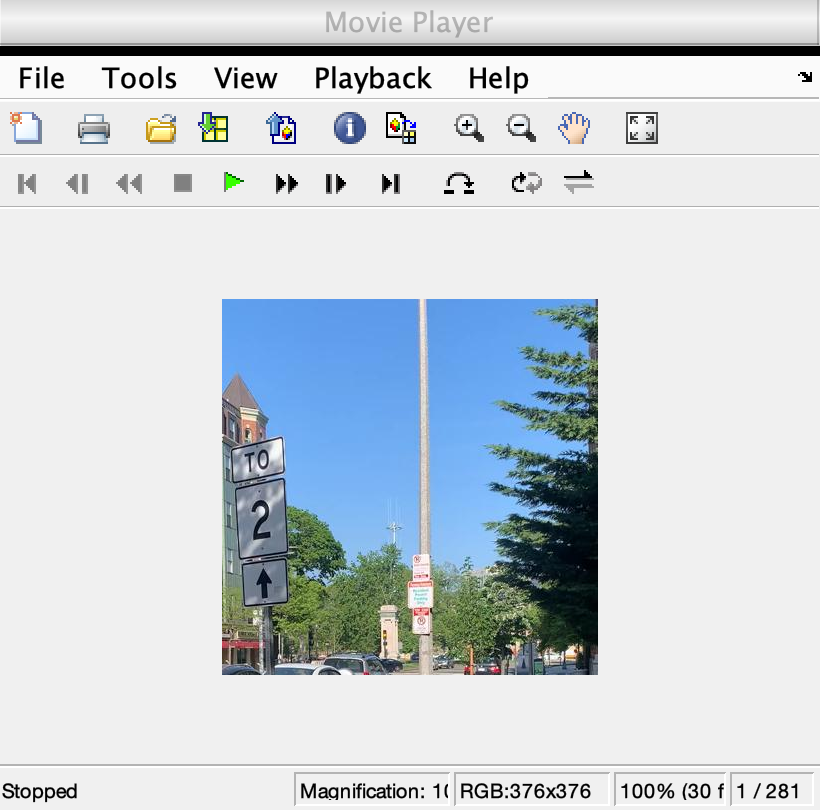

rowIndices = abs(yMinOffset) + 1:nrows - yMaxOffset;

colIndices = abs(xMinOffset) + 1:ncols - xMaxOffset;

### Create the cropped video

This time, use the stabilized video as the initial video. Extract from each frame only the rows and columns that are in every frame.

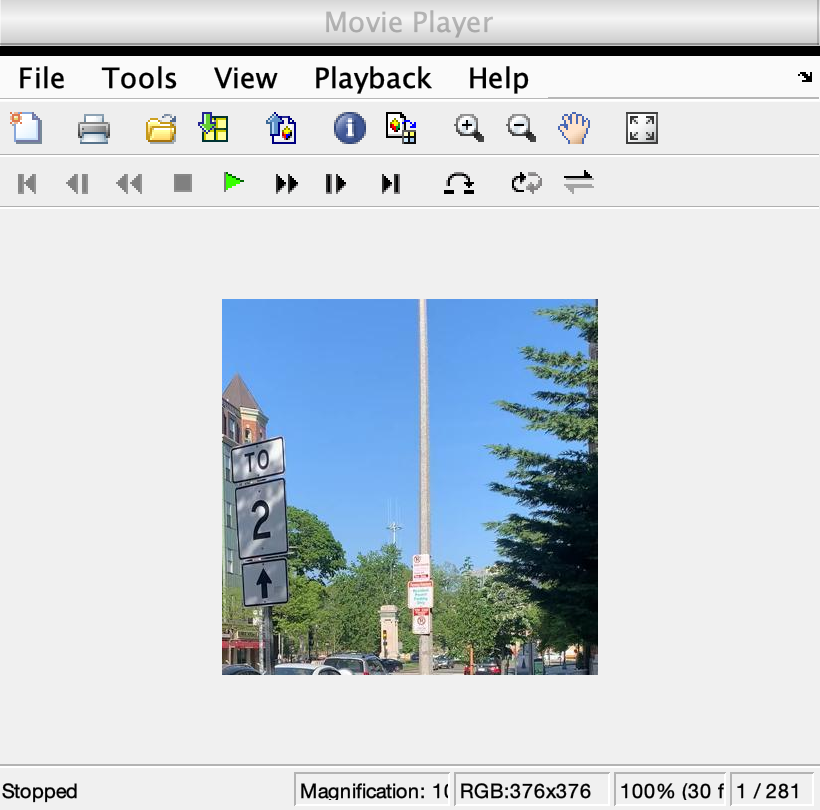

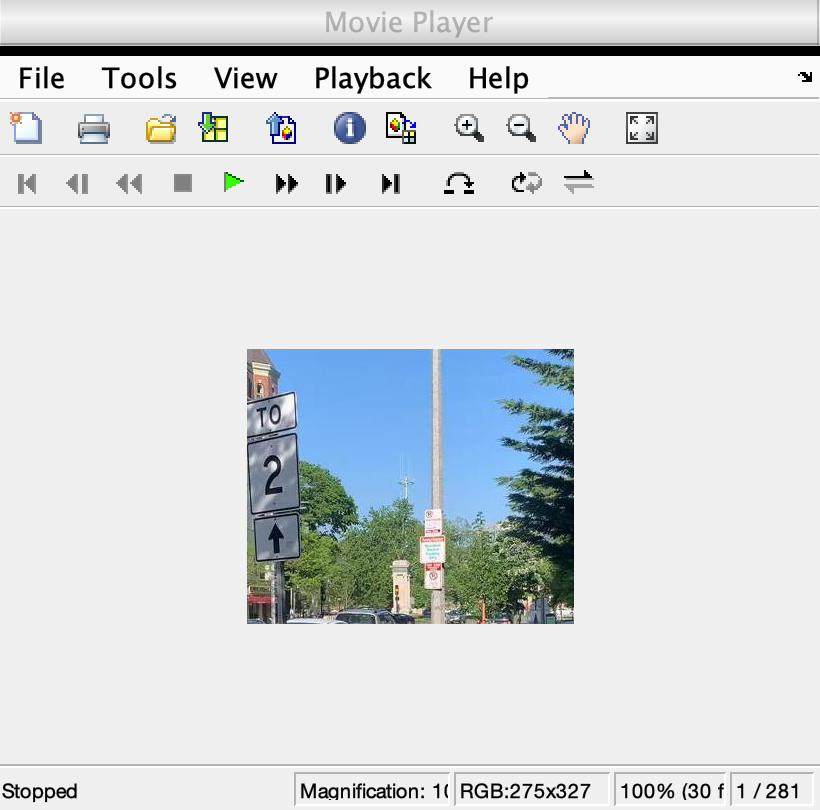

newV = VideoReader("simpleStabilizedVideo.avi");

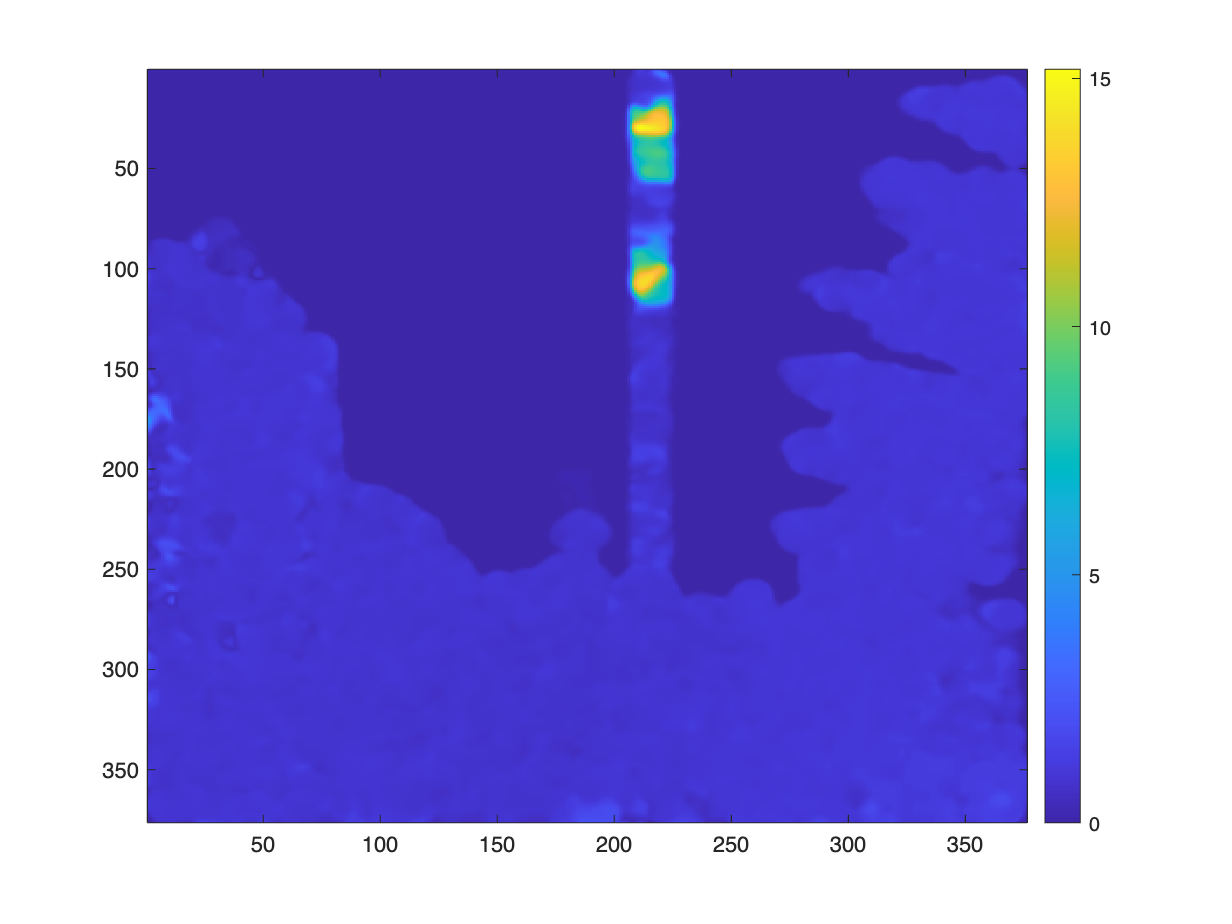

vCropped = VideoWriter("simpleStabilizedVideoCropped.avi");
open(vCropped)
nFrames = newV.NumFrames; 

for jj = 1:nFrames
    frame = read(newV,jj);
    % Extract only the rows and columns that appear in every frame
    frame = frame(rowIndices,colIndices,:);

    % Write the new image to the cropped video
    writeVideo(vCropped,frame)
end
close(vCropped)

implay("ShakyStreet.avi")
figure
implay("simpleStabilizedVideo.avi")
figure

implay("simpleStabilizedVideoCropped.avi")

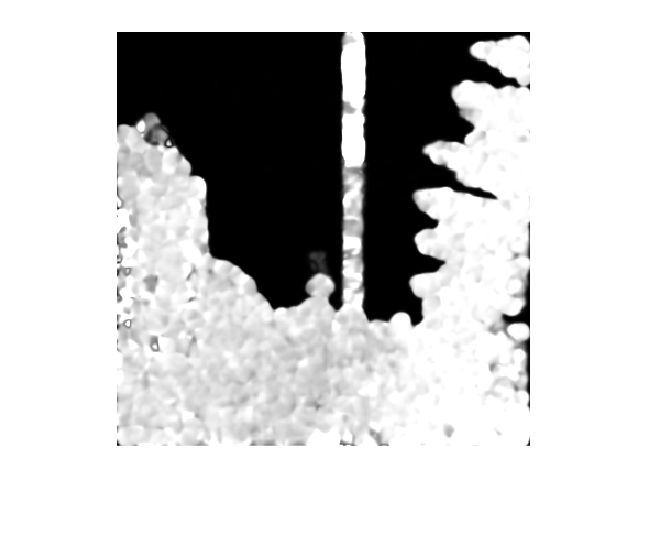

img11 = read(VideoReader("ShakyStreet.avi"), 55);
img12 = read(VideoReader("ShakyStreet.avi"), 56);
img21 = read(VideoReader("simpleStabilizedVideoCropped.avi"), 55);

img22 = read(VideoReader("simpleStabilizedVideoCropped.avi"), 56);

of = opticalFlowFarneback;

ans = single
0.6327

estimateFlow(of, im2gray(img11));

ans = single
0.3806


flow12 = estimateFlow(of, im2gray(img12));

of1 = opticalFlowFarneback;
estimateFlow(of1, im2gray(img21));
flow22 = estimateFlow(of1, im2gray(img22));

imagesc(flow12.Magnitude)
colorbar

magThresh = 0.25;
mask = (flow12.Magnitude > magThresh);
imshow()

mean(flow12.Magnitude(:))

mean(flow22.Magnitude(:))

*Copyright 2022 The MathWorks, Inc.*